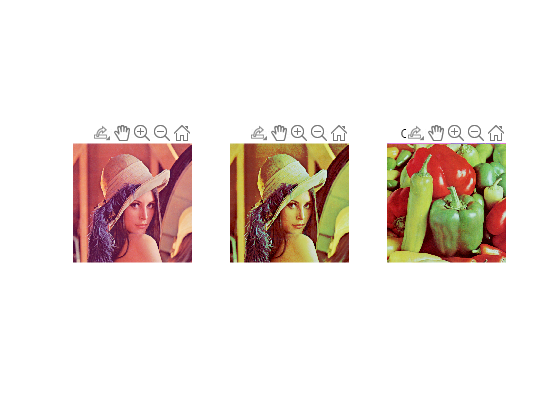

% Load the images
lena = imread('images/lena_color.tif');
peppers = imread('images/peppers_color.tif');


% Compute the histograms of the images
num_bins = 256;
lena_hist = zeros(3,num_bins);
peppers_hist = zeros(3,num_bins);
for k = 1:3
    for i = 1:size(lena,1)
        for j = 1:size(lena,2)
            lena_hist(k,lena(i,j,k)+1) = lena_hist(k,lena(i,j,k)+1) + 1;
            peppers_hist(k,peppers(i,j,k)+1) = peppers_hist(k,peppers(i,j,k)+1) + 1;
        end
    end
end

% Compute the cumulative histograms of the images
lena_cumulative_hist = zeros(3,num_bins);
peppers_cumulative_hist = zeros(3,num_bins);
for k = 1:3
    for i = 1:num_bins
        lena_cumulative_hist(k, i) = sum(lena_hist(k, 1:i)) / numel(lena(:,:,k));
        peppers_cumulative_hist(k, i) = sum(peppers_hist(k, 1:i)) / numel(peppers(:,:,k));
    end
end

% Perform histogram matching
matched_lena = lena;
for i = 1:size(lena,3)
    for j = 1:size(lena,1)
        for k = 1:size(lena,2)
            % Find the intensity value in the reference image that matches
            % the current pixel in the input image
            diff = abs(peppers_cumulative_hist(i, :) - lena_cumulative_hist(i, lena(j,k,i)+1));
            [~, idx] = min(diff);
            
            % Map the intensity value in the input image to the matched value
            matched_lena(j,k,i) = idx - 1;
        end
    end
end

% Display the original and matched images side by side
figure;
subplot(1,3,1);
imshow(lena);
title('Original Lena');
subplot(1,3,2);
imshow(matched_lena);
title('Matched Lena');
subplot(1,3,3);
imshow(peppers);
title('Original Peppers');